ks=readmatrix("Knapsack.xlsx")

ks =      1   114    50
     2    90    50
     3    75    80
     4    80    10
     5    55    10
     6   140    30
     7   120    50
     8   105    80
     9    66   100
    10    98    20



peso=ks(:,2)

peso =    114
    90
    75
    80
    55
   140
   120
   105
    66
    98



valore=ks(:,3)

valore =     50
    50
    80
    10
    10
    30
    50
    80
   100
    20



f=-valore

f =    -50
   -50
   -80
   -10
   -10
   -30
   -50
   -80
  -100
   -20



A=peso'

A =    114    90    75    80    55   140   120   105    66    98   165   110




b=1000;

lb = zeros(length(A),1)

lb =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


ub = ones (length(A),1)

ub =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1



intcon = 1:1:length(A)

intcon =      1     2     3     4     5     6     7     8     9    10    11    12



intlinprog (f,intcon,A,b,[],[],lb,ub)

Running HiGHS 1.7.0: Copyright (c) 2024 HiGHS under MIT licence terms
Coefficient ranges:
  Matrix [6e+01, 2e+02]
  Cost   [1e+01, 1e+02]
  Bound  [1e+00, 1e+00]
  RHS    [1e+03, 1e+03]
Presolving model
1 rows, 12 cols, 12 nonzeros  0s
1 rows, 12 cols, 12 nonzeros  0s
Objective function is integral with scale 0.1

Solving MIP model with:
   1 rows
   12 cols (12 binary, 0 integer, 0 implied int., 0 continuous)
   12 nonzeros

        Nodes      |    B&B Tree     |            Objective Bounds              |  Dynamic Constraints |       Work      
     Proc. InQueue |  Leaves   Expl. | BestBound       BestSol              Gap |   Cuts   InLp Confl. | LpIters     Time

         0       0         0   0.00%   -590            inf                  inf        0      0      0         0     0.0s
 S       0       0         0   0.00%   -590            -550               7.27%        0      0      0         0     0.0s

Solving report
  Status            Optimal
  Primal bound      -550
  Dual bound

ans =      1
     1
     1
     0
     0
     1
     1
     1
     1
     0


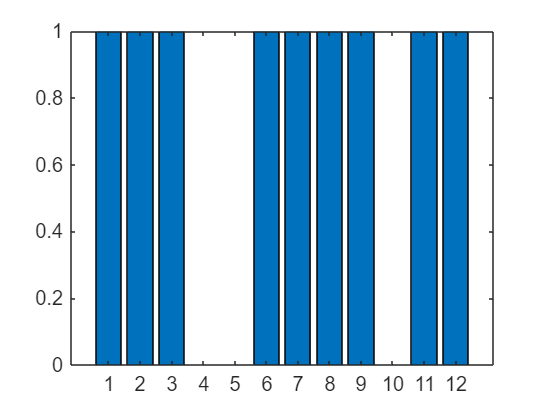


bar (ans)